% Tolerance Explorer Live Script
% The purpose of this script is to develop robust tolerances
% For localization data and then save the finalized result to 
% The appropriate folder
clearvars;
close all;
clc;
files= dir('*combo*');
numel(files)

ans = 24

try
load('C:\Users\ajnel\Documents\GitHub\Matlab-Master\Hurricane\Tolfile.mat');
catch
    load('C:\Users\AJN Lab\Documents\GitHub\Matlab-Master\Hurricane\Tolfile.mat');
    
end
colors = {'red','orange'};


% Load file and populate fractionals
file = 1;

disp(['Loading ', files(file).name])

Loading cell_1_dast_combo.mat


load(files(file).name)
c = 2;
color = colors{c}

color = 'orange'

try
cdata.(color).fr_N =  cdata.(color).crlbs(:,3).^0.5./cdata.(color).fits(:,3);
cdata.(color).fr_sx = cdata.(color).crlbs(:,4).^0.5./cdata.(color).fits(:,4);
cdata.(color).fr_sy = cdata.(color).crlbs(:,5).^0.5./cdata.(color).fits(:,5);
cdata.(color).fr_o =  cdata.(color).crlbs(:,6).^0.5./cdata.(color).fits(:,6);
cdata.(color).ilv = cdata.(color).llv(:)./cdata.(color).fits(:,3);
cdata.(color).eps = abs(cdata.(color).fits(:,4)./cdata.(color).fits(:,5));
cdata.(color).snr =(cdata.(color).fits(:,3)./(cdata.(color).fits(:,3)+(2*6+1)^2*cdata.(color).fits(:,6)).^0.5);
catch
end
c = 1;
color = colors{c}

color = 'red'

try
cdata.(color).fr_N =  cdata.(color).crlbs(:,3).^0.5./cdata.(color).fits(:,3);
cdata.(color).fr_sx = cdata.(color).crlbs(:,4).^0.5./cdata.(color).fits(:,4);
cdata.(color).fr_sy = cdata.(color).crlbs(:,5).^0.5./cdata.(color).fits(:,5);
cdata.(color).fr_o =  cdata.(color).crlbs(:,6).^0.5./cdata.(color).fits(:,6);
cdata.(color).ilv = cdata.(color).llv(:)./cdata.(color).fits(:,3);
cdata.(color).eps = abs(cdata.(color).fits(:,4)./cdata.(color).fits(:,5));
cdata.(color).snr =(cdata.(color).fits(:,3)./(cdata.(color).fits(:,3)+(2*6+1)^2*cdata.(color).fits(:,6)).^0.5);
catch
end
% Investigate Color-based tolearnces
close all
c = 1;
color = colors{c}

color = 'red'

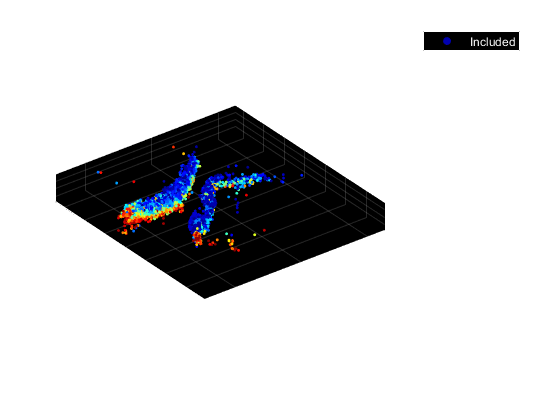

 % keep this value based on spline correction, if this is poorly choosen we should end up seeing
 % a splaying of the data along a direction
tol.r.zlims = [-0.9 0.97];
tol.r.dist = 0.6;
tol.q = cal.q;
% Investigating Limits on Absolute Z position
ind = cdata.(color).distance < tol.r.dist; % axial tolerances


scatter3(cdata.(color).xf(ind),cdata.(color).yf(ind),cdata.(color).zf(ind),5,cdata.(color).framenumber(ind),'filled')
hold on
% ind = logical(1-ind);
% scatter3(cdata.(color).xf(ind),cdata.(color).yf(ind),cdata.(color).zf(ind),5,'filled')
hold off
legend('Included','Excluded')
axis equal
zlim(tol.r.zlims)
colormap('jet')

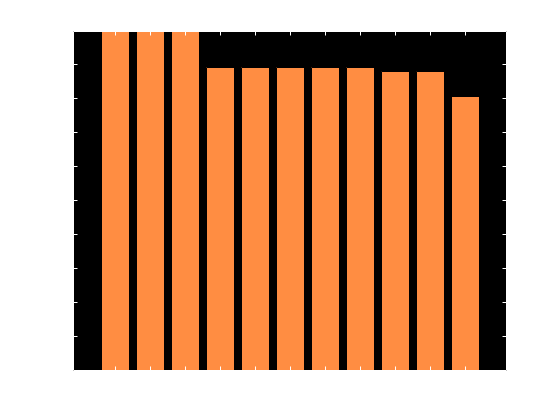

counts = [];


% Build Red
ind = cdata.(color).fits(:,3) > tol.r.N_tol(1) & cdata.(color).fits(:,3) < tol.r.N_tol(2); % Photon Tolerance
counts(1) = sum(ind);
ind = ind & cdata.(color).snr >= tol.r.minsnr; % Signal to Noise tolerances
counts(2) = sum(ind);
ind = ind & abs(cdata.(color).framenumber - mean(tol.r.flims)) <= diff(tol.r.flims)/2; % Framenumber tolerances
counts(3) = sum(ind);
ind = ind & cdata.(color).distance < tol.r.dist;
counts(4) = sum(ind);
ind = ind & abs(cdata.(color).fits(:,6)-mean(tol.r.offlim)) <= diff(tol.r.offlim)/2;   % offset tolerances
counts(5) = sum(ind);
ind = ind & (abs(cdata.(color).fits(:,4)).*abs(cdata.(color).fits(:,5))).^0.5 > tol.r.s_tol(1) & (abs(cdata.(color).fits(:,4)).*abs(cdata.(color).  fits(:,5))).^0.5 < tol.r.s_tol(2); % sigma Tolerance
counts(6) = sum(ind);
ind = ind & tol.q*cdata.(color).crlbs(:,1).^.5 < tol.r.lat_max & tol.q*cdata.(color).crlbs(:,2).^.5 < tol.r.lat_max; % Lateral Uncertainty Tolerance
counts(7) = sum(ind);
ind = ind & cdata.(color).ilv > tol.r.iln; % llv tolerance
counts(8) = sum(ind);
ind = ind & cdata.(color).fr_N < tol.r.frac_lim & abs(cdata.(color).fr_o) < tol.r.off_frac; % Fraction photon tolerance
counts(9) = sum(ind);
ind = ind & cdata.(color).fr_sx < tol.r.frac_lim & cdata.(color).fr_sy < tol.r.frac_lim; % Fraction width tolerance
counts(10) = sum(ind);
ind = ind & abs(cdata.(color).zf-mean(tol.r.zlims)) <= diff(tol.r.zlims)/2; % axial tolerances
counts(11) = sum(ind);
bar(counts./numel(cdata.(color).zf))
axes = gca;
set(gca,'XtickLabel',{'N','SNR','Time','Zf','Offset','\sigma','LP','LLV','Fr_N','Fr_\sigma','D_\sigma'})
axis auto
ylabel('Percentage Past Threshold')
xlabel('Threshold')
title('Localization Survival Chart')

% Save the new file once satified
save('C:\Users\AJN Lab\Documents\GitHub\Matlab-Master\Hurricane\Tolfile.mat','tol');

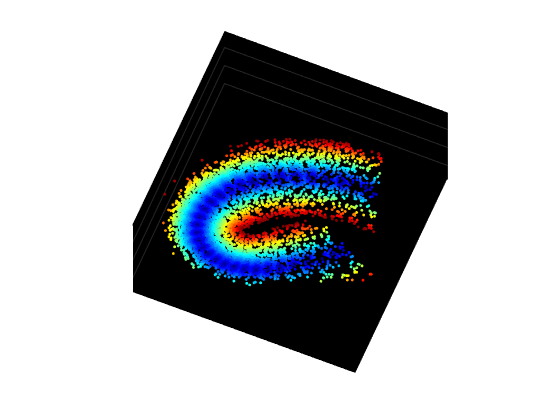

% Tolerance Investigating distance away from 
tol.r.dist = 0.6;
ind = abs(cdata.(color).zf-mean(tol.r.zlims)) <= diff(tol.r.zlims)/2; % axial tolerances
ind = ind & cdata.(color).distance < tol.r.dist;
scatter3(cdata.(color).fits(ind,4),cdata.(color).fits(ind,5),cdata.(color).zf(ind),5,cdata.(color).distance(ind),'filled')
% axis equal
whitebg([0 0 0 ])
set(gca,'Xtick',[])
set(gca,'Ytick',[])
axis equal

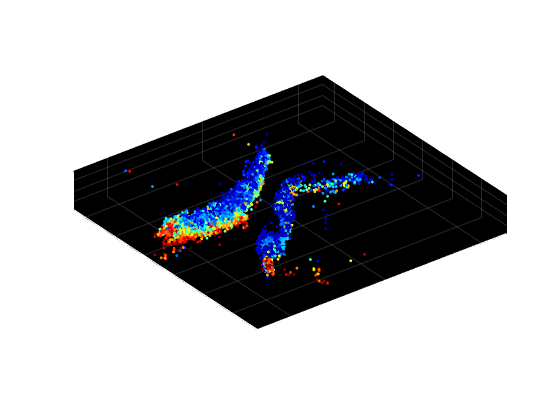

% % histogram
% histogram(cdata.(color).distance,'Normalization','probability')
% axes = gca;
% xlims = axes.XLim;
% ylims = axes.YLim;
% hold on
% plot([tol.r.dist,tol.r.dist], [0,1],'r')
% % plot([tol.r.zlims(2),tol.r.zlims(2)], [0,1],'r')
% hold off
% xlim(xlims)
% ylim(ylims)
% title('SNR')

scatter3(cdata.(color).xf(ind),cdata.(color).yf(ind),cdata.(color).zf(ind),5,cdata.(color).framenumber(ind),'filled')
axis equal